# **MATLAB PROJECT: FIRST PART**

Group 16

Our group is composed by:

- Belhassenn Ali (273771)

- Dospinescu Sara (268541)

- Ivashkevich Alessandro (276871)

- Staglioli Matteo (259181)

## Task 1:

Import the dataset in MATLAB

We have imported data from a .xslx file thanks to the easiest procedure: clicking on *Import Data *in the Home Tab of the main MATLAB window and selecting the file whose data we want to import. Moreover we converted data's table into a numeric matrix.

save 'Powerplantdata' Powerplantdata

## Task 2:

Each column represent a vector of values. In order to save some variables we write the variable name after the file name

We have 4 independent variables and one dependent variable, "Energyoutput",  which is affected by them.

Ambienttemperature= Powerplantdata(:,1);
Exhaustvacuum = Powerplantdata(:,2);
Ambientpressure = Powerplantdata(:,3);
Relativehumidity = Powerplantdata(:,4);

Energyoutput = Powerplantdata(:,5);

## Task 3:

Now we're going to generate four distinct scatterplots of the response variable vs. each of the regressors.

We have plotted the scatterplots of the four variables thanks to some some built-in functions of matlab.

#### energyoutput vs ambienttemperature

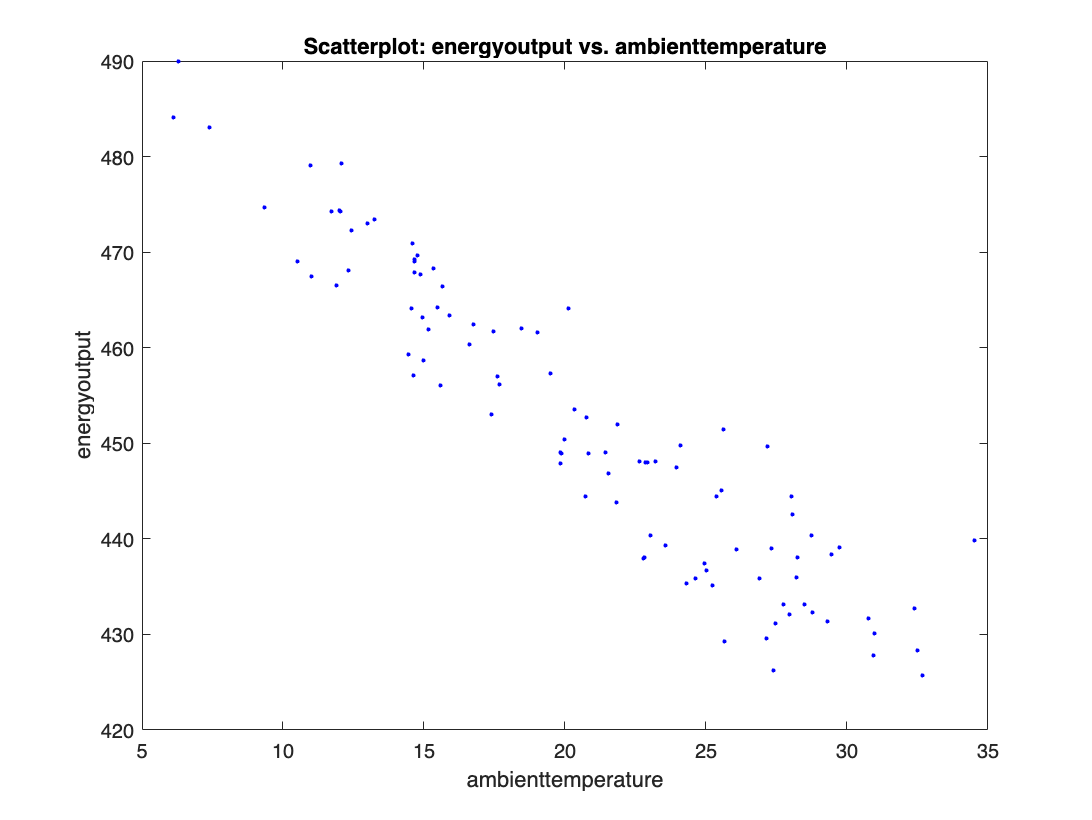

figure()
plot(Ambienttemperature, Energyoutput,'b.')
ylabel('energyoutput')
xlabel('ambienttemperature')
title('Scatterplot: energyoutput vs. ambienttemperature')

#### energyoutput vs exhaustvacuum

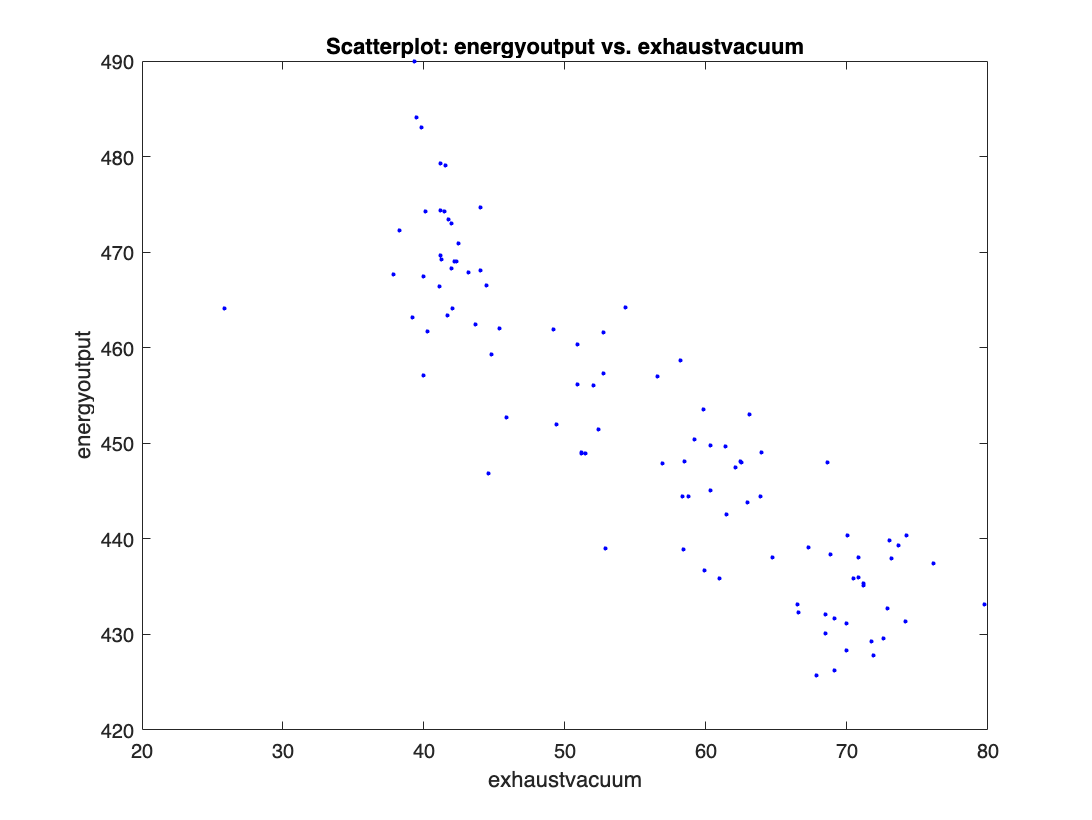

figure()
plot(Exhaustvacuum, Energyoutput,'b.')
ylabel('energyoutput')
xlabel('exhaustvacuum')
title('Scatterplot: energyoutput vs. exhaustvacuum')

#### energyoutput vs ambientpressure

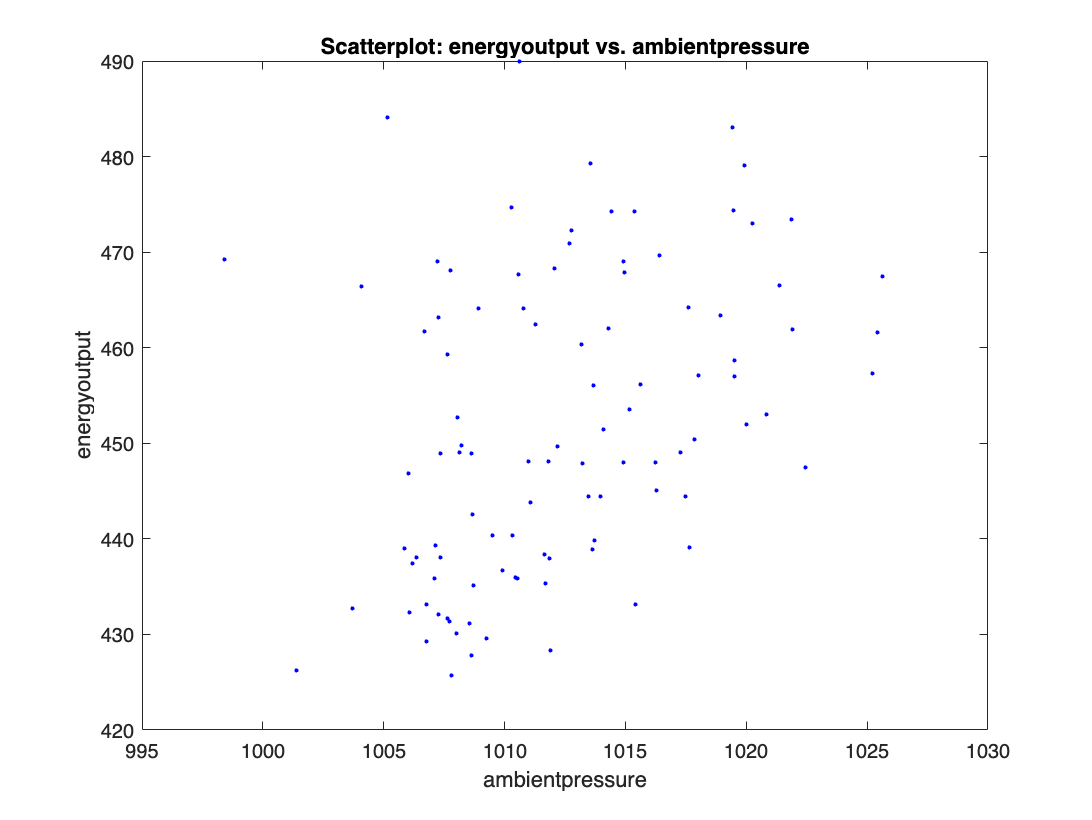

figure()
plot(Ambientpressure, Energyoutput,'b.')
ylabel('energyoutput')
xlabel('ambientpressure')
title('Scatterplot: energyoutput vs. ambientpressure')

#### energyoutput - relativehumidity

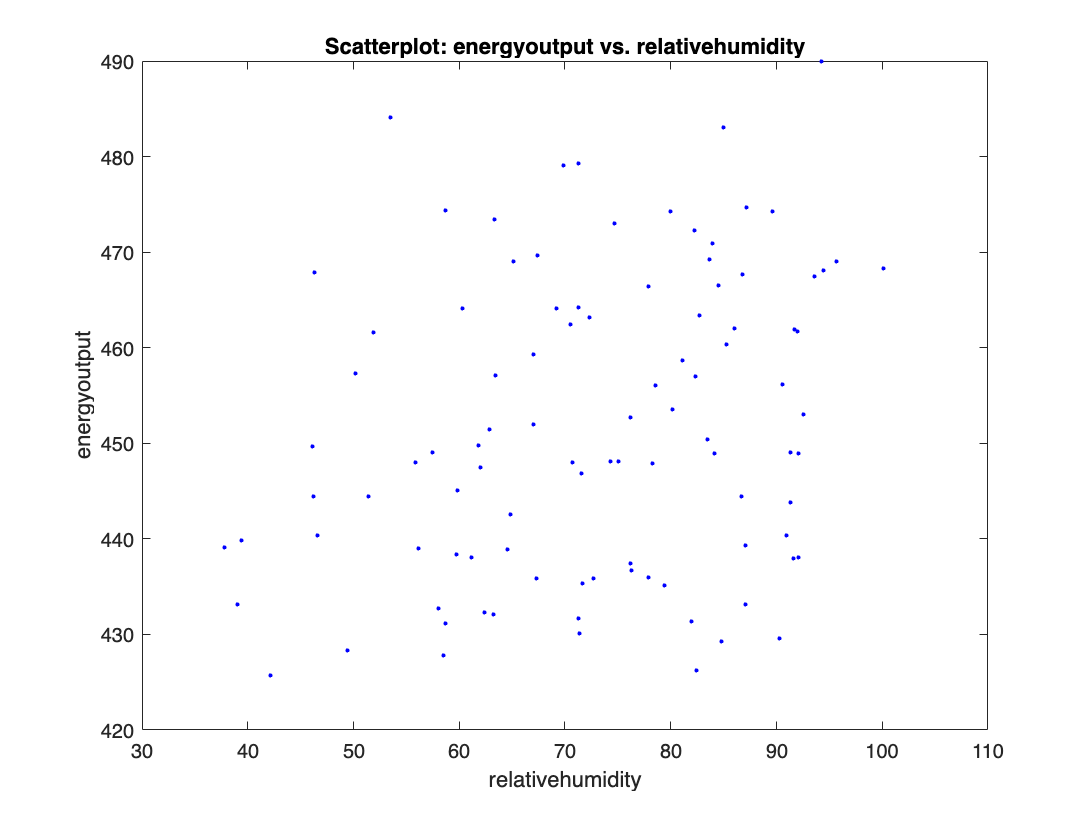

figure()
plot(Relativehumidity, Energyoutput,'b.')
ylabel('energyoutput')
xlabel('relativehumidity')
title('Scatterplot: energyoutput vs. relativehumidity')

## Task 4:

The best linear model that fits a model describing the following relationship between observations $x_i$, dependent variables, and $y_i$, prices:

$y_i = \beta_0 + \beta_1 x_i + \varepsilon_i$, $i = 1, \dots, m$,

where m is the number of observations in our dataset, is the one that has the optimal coefficients. So we introduce:

$\mathbf y = \left[\matrix{y_1 \cr \vdots \cr y_m}\right]$, the vector of the response variable;

$X= \left[\matrix{1 & x_1 \cr \vdots & \vdots \cr 1 & x_m}\right]$, the design matrix;

$\mathbf \beta = \left[\matrix{\beta_0 \cr \beta_1}\right]$, the vector of coefficients;

$\mathbf \varepsilon = \left[\matrix{\varepsilon_1 \cr \vdots \cr \varepsilon_m}\right]$, the vector of residuals.

Now we need to minimize the *residual sum of squares *$||\mathbf \varepsilon||^2 = ||\mathbf y - X \mathbf \beta||^2 =: f(\mathbf \beta)$.

If $X$ has linearly independent columns (i.e., $X^TX$ is invertible), then $f$ has a unique global minimum point $\hat \mathbf \beta$, which gives us the coefficients of *the* best linear model fitting the data:

$\hat \mathbf \beta = (X^TX)^{-1}X^T\mathbf y$.

#### For energyoutput-ambienttemperature

m1 = length(Ambienttemperature);
X1 = [ones(m1,1) Ambienttemperature];
beta_hat1 = inv(X1.'*X1)*X1.'*Energyoutput

beta_hat1 =   496.9862
   -2.1779


#### For energyoutput-exhaustvacuum

m2 = length(Exhaustvacuum);
X2 = [ones(m2,1) Exhaustvacuum];
beta_hat_2 = inv(X2.'*X2)*X2.'*Energyoutput

beta_hat_2 =   513.6218
   -1.1090


#### For energy-ambientpressure

m3 = length(Ambientpressure);
X3 = [ones(m3,1) Ambientpressure];
beta_hat_3 = inv(X3.'*X3)*X3.'*Energyoutput

beta_hat_3 =  -625.5544
    1.0643


#### For energy-relativehuminity

m4 = length(Relativehumidity);
X4 = [ones(m4,1) Relativehumidity];
beta_hat_4 = inv(X4.'*X4)*X4.'*Energyoutput

beta_hat_4 =   432.3060
    0.2690


## Task 5:

In order to plot the regression line on each of the corresponding scatterplots, we have re-plotted it and thanks to the matlab function "hold on", we can plot its regression line.

#### For energy-ambienttemperature

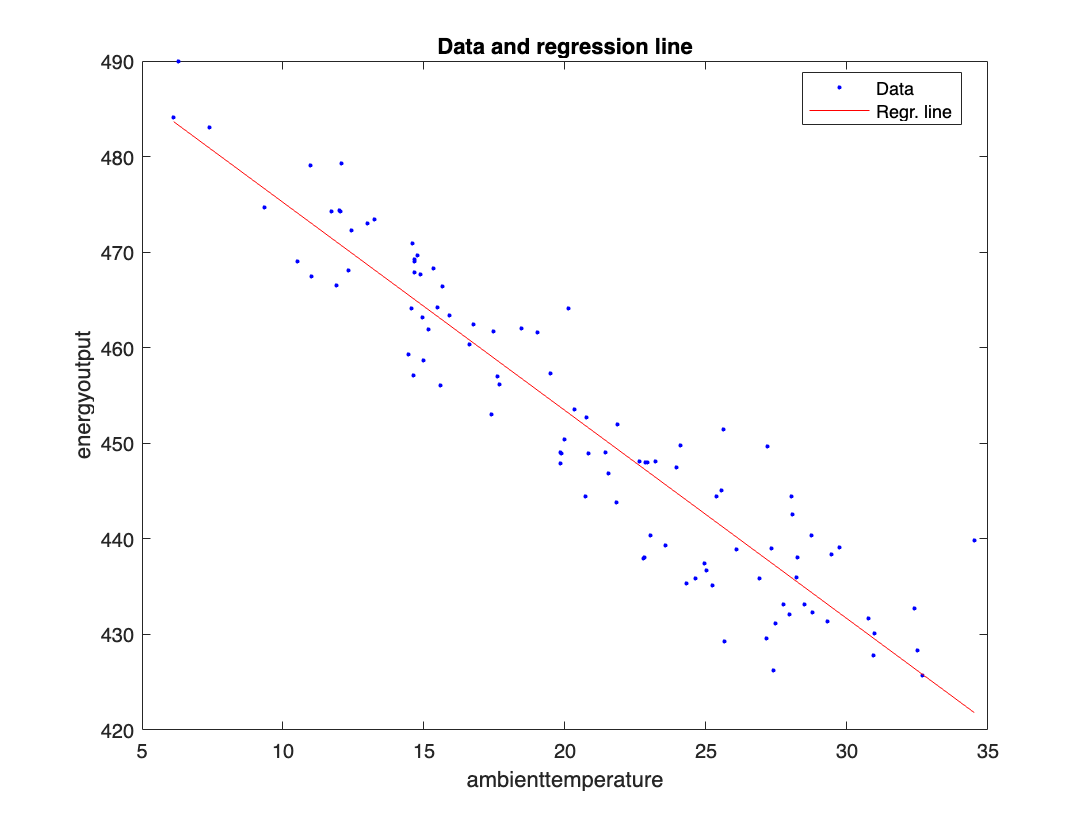

fitted_v_1 = X1*beta_hat1;
figure()
plot(Ambienttemperature,Energyoutput,'b.','DisplayName','Data')
hold on
plot(Ambienttemperature,fitted_v_1, 'r-', 'DisplayName','Regr. line')
xlabel('ambienttemperature')
ylabel('energyoutput')
title('Data and regression line')
legend('Location','best')
hold off

#### For energyoutput-exhaustvacuum

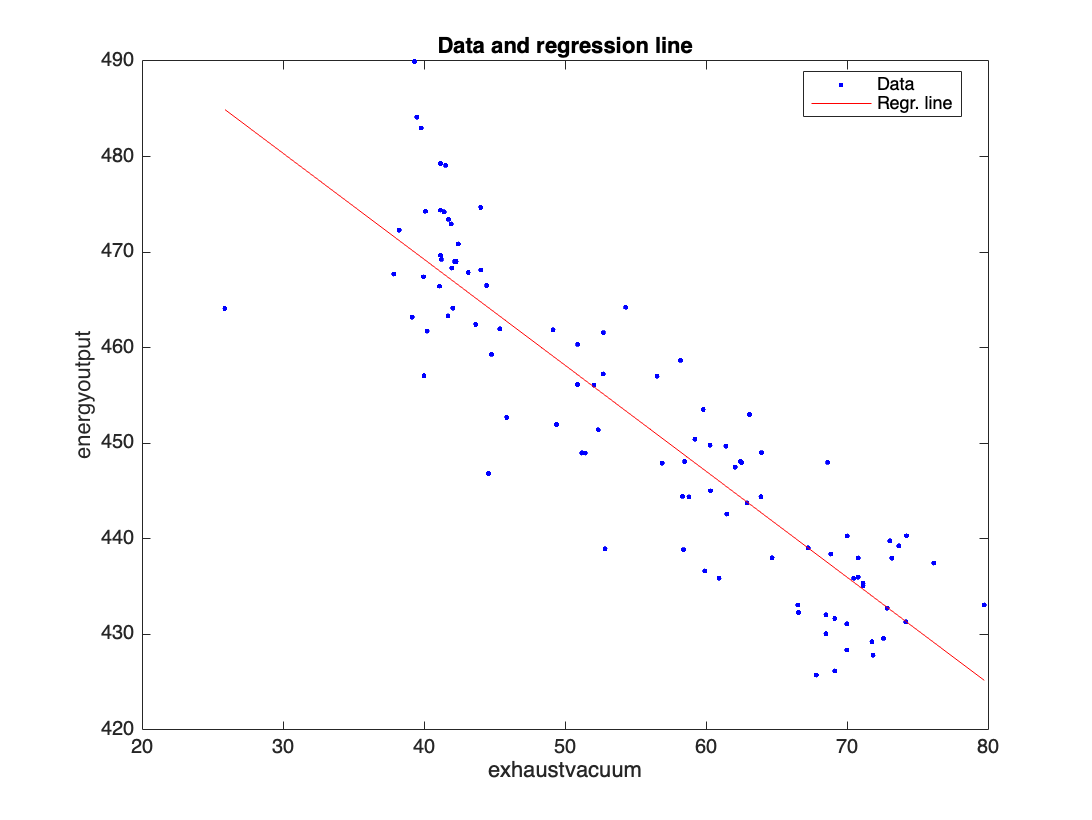

fitted_v_2 = X2*beta_hat_2;
figure()
plot(Exhaustvacuum,Energyoutput,'b.','DisplayName','Data')
hold on
plot(Exhaustvacuum,fitted_v_2, 'r-', 'DisplayName','Regr. line')
xlabel('exhaustvacuum')
ylabel('energyoutput')
title('Data and regression line')
legend('Location','best')
hold off

#### For energyoutput-ambientpressure

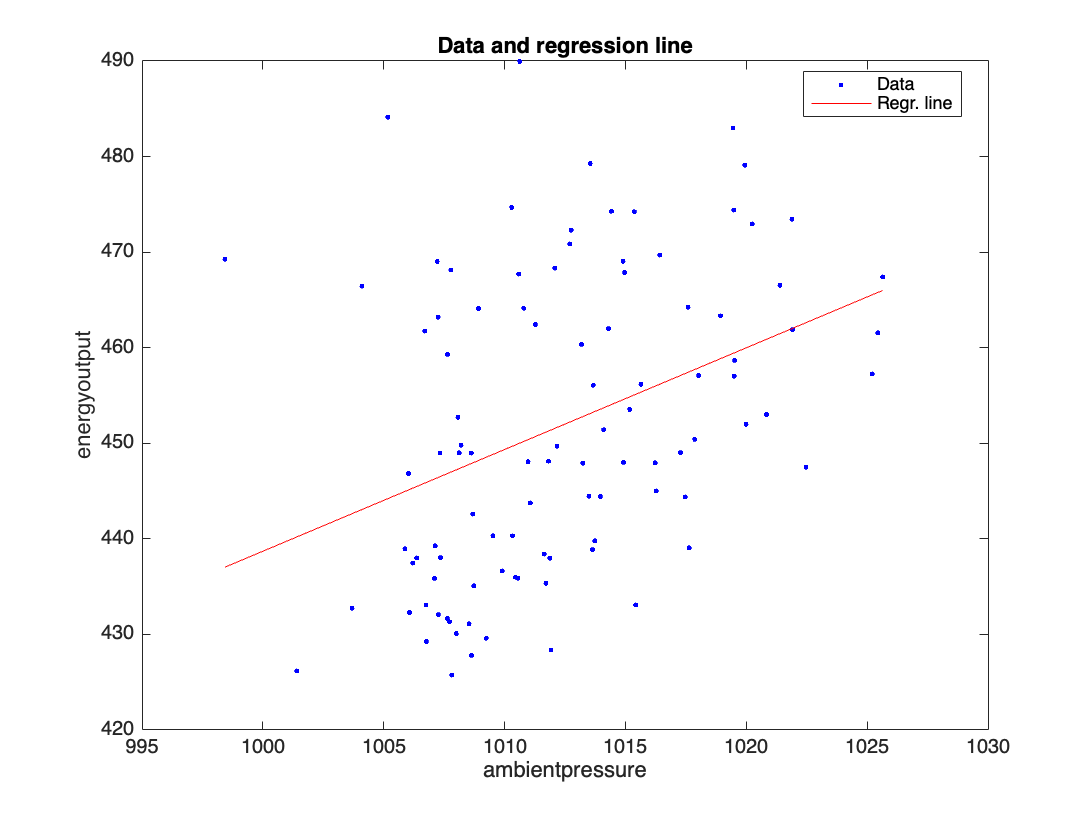

fitted_v_3 = X3*beta_hat_3;
figure()
plot(Ambientpressure,Energyoutput,'b.','DisplayName','Data')
hold on
plot(Ambientpressure,fitted_v_3, 'r-', 'DisplayName','Regr. line')
xlabel('ambientpressure')
ylabel('energyoutput')
title('Data and regression line')
legend('Location','best')
hold off

#### For energyoutput-relativehuminity

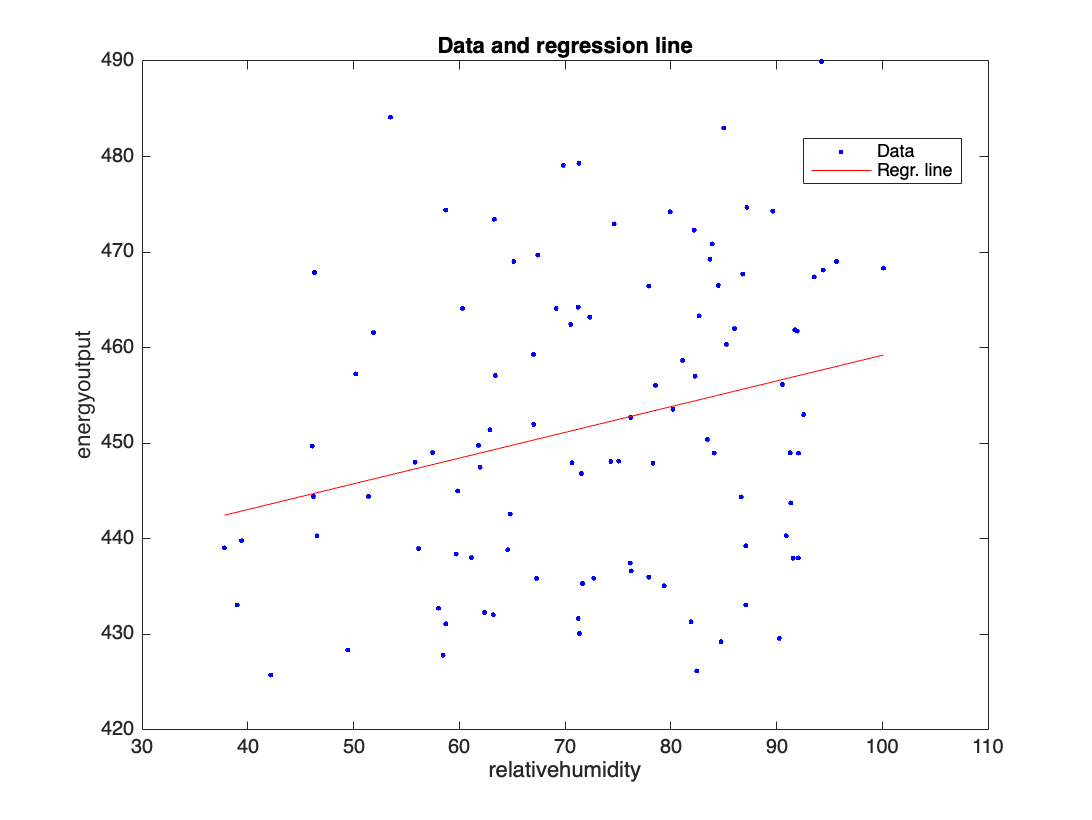

fitted_v_4 = X4*beta_hat_4;
figure()
plot(Relativehumidity,Energyoutput,'b.','DisplayName','Data')
hold on
plot(Relativehumidity,fitted_v_4, 'r-', 'DisplayName','Regr. line')
xlabel('relativehumidity')
ylabel('energyoutput')
title('Data and regression line')
legend('Location','best')
hold off

## Task 6:

Compute in MATLAB the root mean square error (RMSE) for each of the models previously obtained. 

We can compute the residual sum of squares and the least-squares error (its square root) in order to make comparisons between models.

Calculating the *mean square error (MSE) *and the *root mean square error (RMSE) *we are accounting for the number of observations. These are defined as follows:

$\mathrm{MSE} = \frac 1m ||y - X\hat\mathbf \beta||^2 = \frac 1m ||\hat\mathbf \epsilon||^2$,


$$\mathrm{RMSE}  = \sqrt{\mathrm{MSE}} = \sqrt{\frac 1m ||\hat\mathbf \epsilon||^2}$$


#### For energyoutput-ambienttemperature

lse1 = norm(Energyoutput - fitted_v_1) % The least-squares error

lse1 = 54.2982

disp(sprintf(' least squares error (lse) = %.3f', lse1))

 least squares error (lse) = 54.298


rss1 = lse1^2 % residual sum of squares

rss1 = 2.9483e+03

disp(sprintf(' residual sum of squares (rss) = %.3f', rss1))

 residual sum of squares (rss) = 2948.290


mse1 = rss1/m1 % The mean square error

mse1 = 29.4829

disp(sprintf('mean square error (mse) = %.3f', mse1))

mean square error (mse) = 29.483


rmse1 = sqrt(mse1) % The root mean square  error

rmse1 = 5.4298

disp(sprintf(' root mean square error (rmse) = %.3f', rmse1))

 root mean square error (rmse) = 5.430


#### For energyoutput-exhaustvacuum

lse2 = norm(Energyoutput - fitted_v_2) % The least-squares error

lse2 = 71.5303

disp(sprintf('least-squares error= %.3f', lse2))

least-squares error= 71.530


rss2 = lse2^2 % The residual sum of squares

rss2 = 5.1166e+03

disp(sprintf('residual sum of squares= %.3f', rss2))

residual sum of squares= 5116.580


mse2 = rss2/m2 % The mean square error

mse2 = 51.1658

disp(sprintf('mean square error= %.3f', mse2))

mean square error= 51.166


rmse2 = sqrt(mse2) % The root mean square error

rmse2 = 7.1530

disp(sprintf('root mean square error is= %.3f', rmse2))

root mean square error is= 7.153


#### For energyoutput-ambientpressure

lse3 = norm(Energyoutput - fitted_v_3) % The least-squares error

lse3 = 144.6319

disp(sprintf('least-squares error = %.3f', lse3))

least-squares error = 144.632


rss3 = lse3^2 % The residual sum of squares

rss3 = 2.0918e+04

disp(sprintf('residual sum of squares is= %.3f', rss3))

residual sum of squares is= 20918.380


mse3 = rss3/m3 % The mean square error

mse3 = 209.1838

disp(sprintf('mean square error is= %.3f', mse3))

mean square error is= 209.184


rmse3 = sqrt(mse3) % The root mean square error

rmse3 = 14.4632

disp(sprintf(' root mean square error = %.3f', rmse3))

 root mean square error = 14.463


#### For energyoutput-relativehumidity 

lse4= norm(Energyoutput - fitted_v_4) % The least-squares error

lse4 = 150.4571

disp(sprintf('least-squares error= %.3f', lse4))

least-squares error= 150.457


rss4 = lse4^2 % The residual sum of squares

rss4 = 2.2637e+04

disp(sprintf('residual sum of squares = %.3f', rss4))

residual sum of squares = 22637.352


mse4= rss4/m4 % The mean square error

mse4 = 226.3735

disp(sprintf('mean square error= %.3f', mse4))

mean square error= 226.374


rmse4 = sqrt(mse4) % The root mean square error

rmse4 = 15.0457

disp(sprintf('root mean square error= %.3f', rmse4))

root mean square error= 15.046


## Task 7:

Try to use the linear models obtained to make some predictions using possible new observations of the regressors.

This problem is interesting as we know that if we choose new observations far away from the range of the range of our independent variable, the prediction would not be so reliable. On the other hand, if the new values fall inside our range the prediction will be much more trustable.

We have decided to solve this problem taking into account the model EnergyOutput vs Ambienttemperature. We start by looking for our range thanks to the min and max functions. Then we put some random values and we do the prediction.

Then we have decided to plot it in order to visualize predictions better. From the graph we can notice that our new observations are falling a lot near the regression line.

**energyoutput-ambienttemperature**

min(Ambienttemperature)

ans = 6.1300

max(Ambienttemperature)

ans = 34.5100

new_ambient = [6 11 17 26 35].'

new_ambient =      6
    11
    17
    26
    35


new_m1 = length(new_ambient);
new_X1= [ones(new_m1,1) new_ambient];
pred_energyoutput = new_X1*beta_hat1;
disp('For the new observations we obtain the following predictions:')

For the new observations we obtain the following predictions:


disp('     1         2         3         4         5')

     1         2         3         4         5


disp(pred_energyoutput.')

  483.9189  473.0296  459.9624  440.3615  420.7607



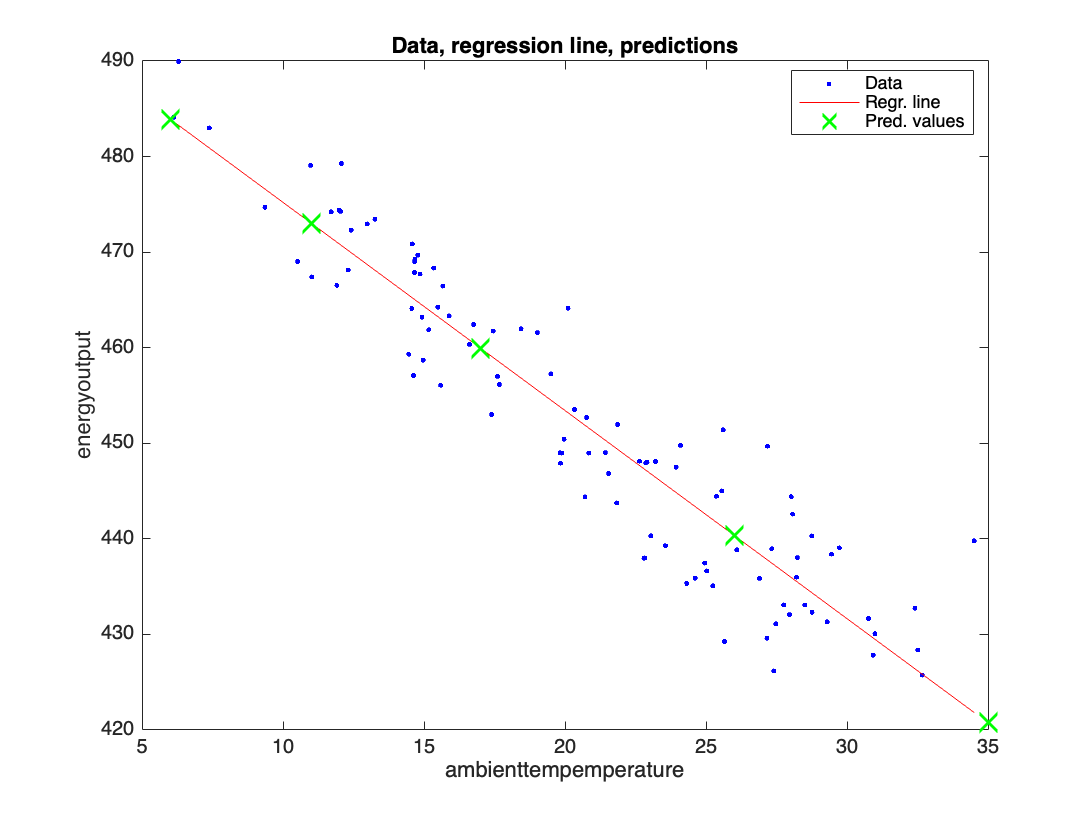


figure()
plot(Ambienttemperature,Energyoutput,'b.','DisplayName','Data')
hold on
plot(Ambienttemperature,fitted_v_1, 'r-', 'DisplayName','Regr. line')
plot(new_ambient,pred_energyoutput, 'gx','MarkerSize',10,'LineWidth',2,'DisplayName', 'Pred. values')
xlabel('ambienttempemperature')
ylabel('energyoutput')
title('Data, regression line, predictions')
legend('Location','best')
hold off

#### energyoutput-exhaustvacuum

min(Exhaustvacuum)

ans = 25.8800

max(Exhaustvacuum)

ans = 79.7400

new_exvac = [26 38 45 62 78].'

new_exvac =     26
    38
    45
    62
    78


new_m1 = length(new_exvac);
new_X1= [ones(new_m1,1) new_exvac];
pred_energyoutput = new_X1*beta_hat1;
disp('For the new observations we obtain the following predictions:')

For the new observations we obtain the following predictions:


disp('     1         2         3         4         5')

     1         2         3         4         5


disp(pred_energyoutput.')

  440.3615  414.2271  398.9820  361.9581  327.1122



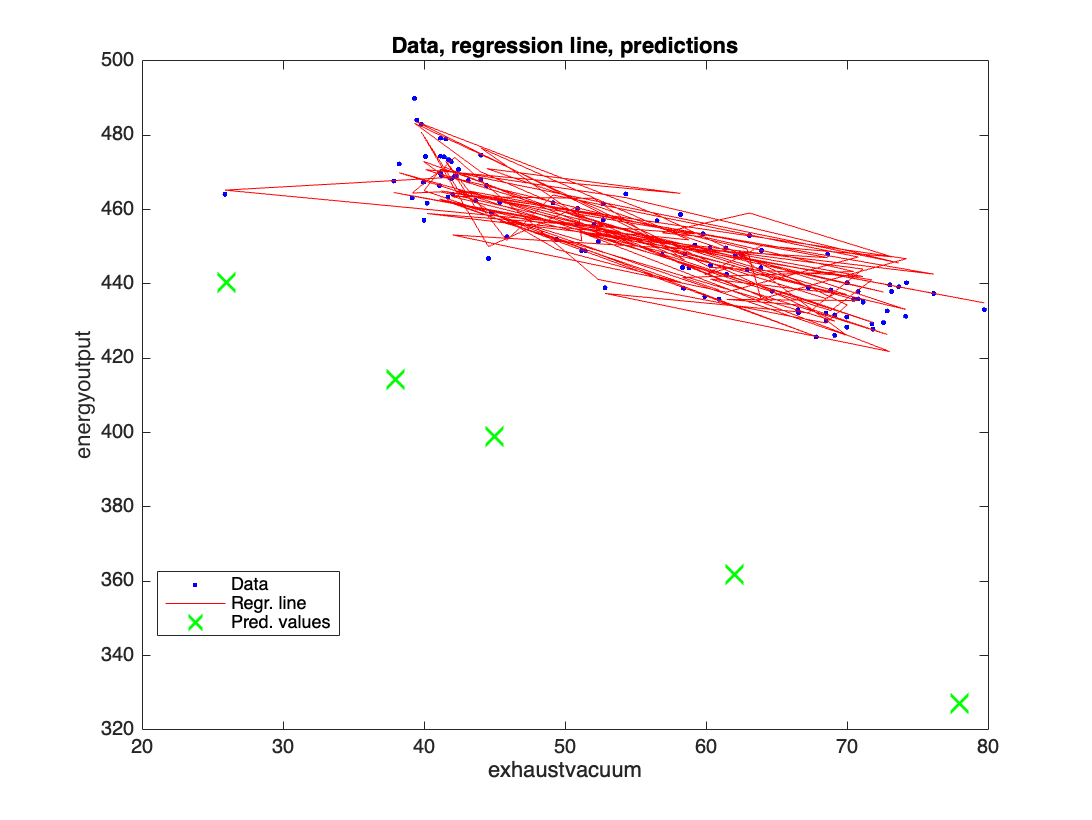


figure()
plot(Exhaustvacuum,Energyoutput,'b.','DisplayName','Data')
hold on
plot(Exhaustvacuum,fitted_v_1, 'r-', 'DisplayName','Regr. line')
plot(new_exvac,pred_energyoutput, 'gx','MarkerSize',10,'LineWidth',2,'DisplayName', 'Pred. values')
xlabel('exhaustvacuum')
ylabel('energyoutput')
title('Data, regression line, predictions')
legend('Location','best')
hold off

#### energyoutput-ambientpressure

min(Ambientpressure)

ans = 998.4300

max(Ambientpressure)

ans = 1.0256e+03

new_ambpr = [50 61 167 224 300].'

new_ambpr =     50
    61
   167
   224
   300


new_m1 = length(new_ambpr);
new_X1= [ones(new_m1,1) new_ambpr];
pred_energyoutput = new_X1*beta_hat1;
disp('For the new observations we obtain the following predictions:')

For the new observations we obtain the following predictions:


disp('     1         2         3         4         5')

     1         2         3         4         5


disp(pred_energyoutput.')

  388.0926  364.1360  133.2816    9.1429 -156.3753



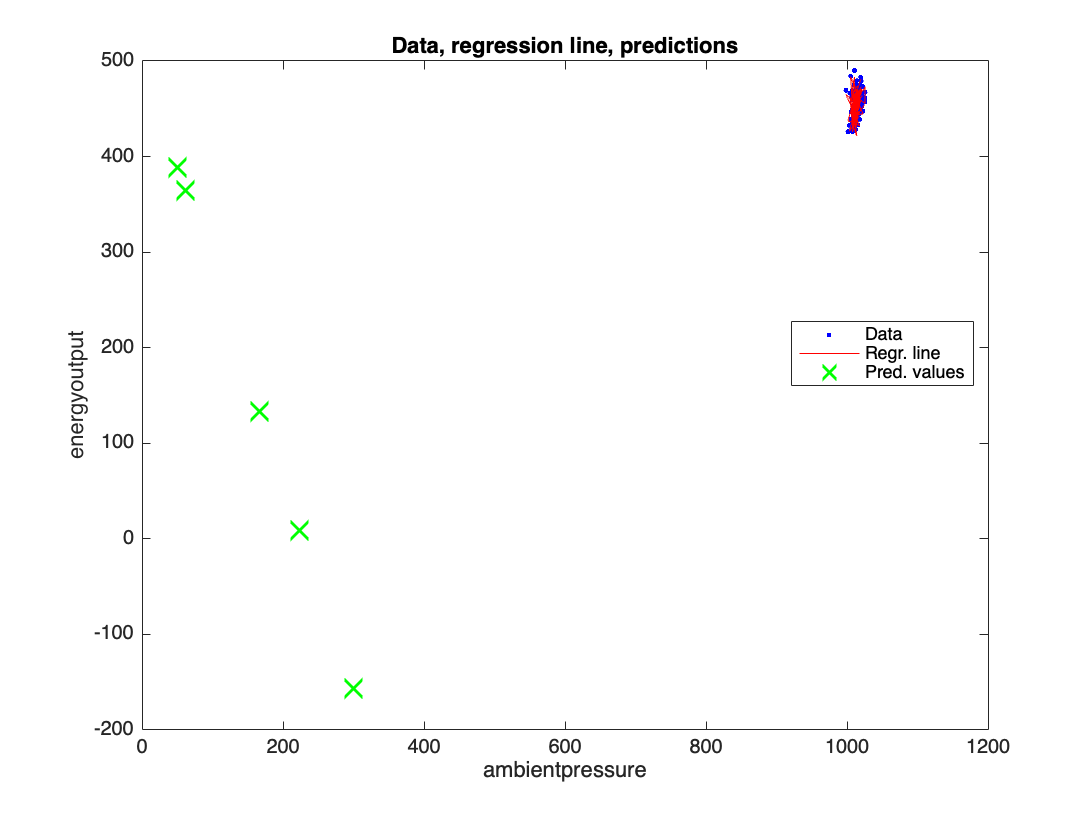


figure()
plot(Ambientpressure,Energyoutput,'b.','DisplayName','Data')
hold on
plot(Ambientpressure,fitted_v_1, 'r-', 'DisplayName','Regr. line')
plot(new_ambpr,pred_energyoutput, 'gx','MarkerSize',10,'LineWidth',2,'DisplayName', 'Pred. values')
xlabel('ambientpressure')
ylabel('energyoutput')
title('Data, regression line, predictions')
legend('Location','best')
hold off

#### energyoutput-relativehumidity

min(Relativehumidity)

ans = 37.7900

max(Relativehumidity)

ans = 100.1200

new_relh = [10 50 120 200 1000].'

new_relh =           10
          50
         120
         200
        1000


new_m1 = length(new_relh);
new_X1= [ones(new_m1,1) new_relh];
pred_energyoutput = new_X1*beta_hat1;
disp('For the new observations we obtain the following predictions:')

For the new observations we obtain the following predictions:


disp('     1         2         3         4         5')

     1         2         3         4         5


disp(pred_energyoutput.')

   1.0e+03 *

    0.4752    0.3881    0.2356    0.0614   -1.6809



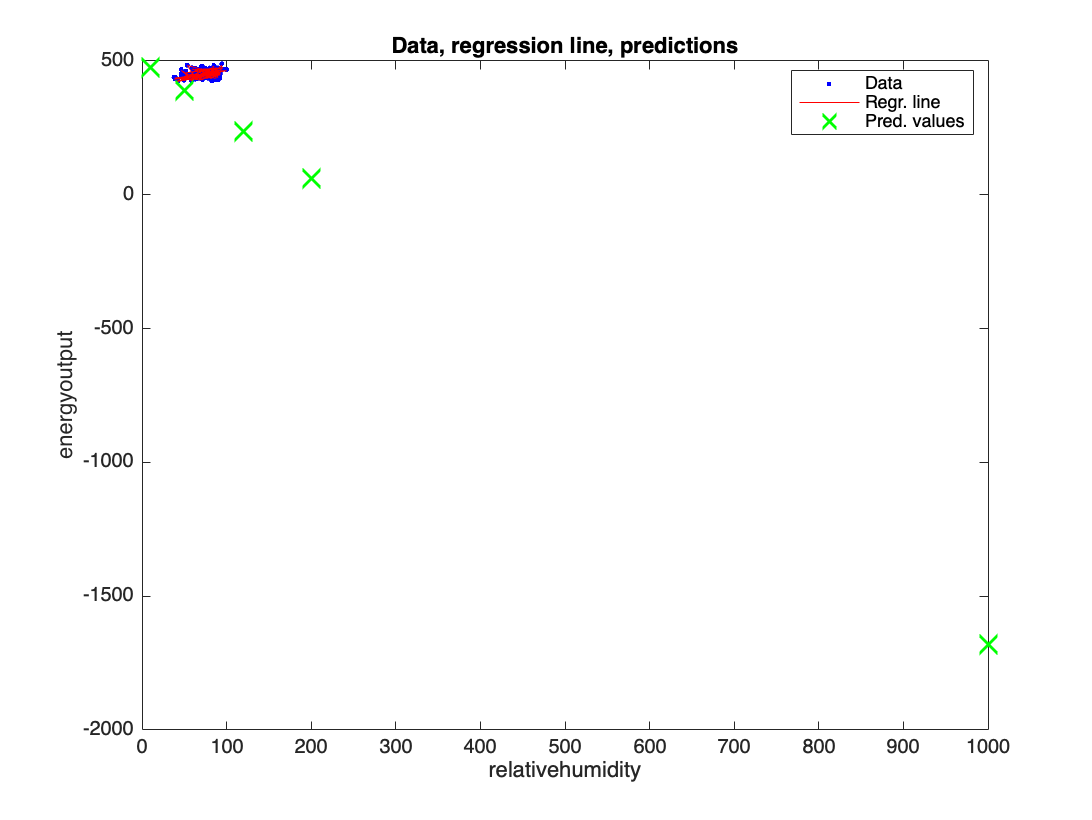


figure()
plot(Relativehumidity,Energyoutput,'b.','DisplayName','Data')
hold on
plot(Relativehumidity,fitted_v_1, 'r-', 'DisplayName','Regr. line')
plot(new_relh,pred_energyoutput, 'gx','MarkerSize',10,'LineWidth',2,'DisplayName', 'Pred. values')
xlabel('relativehumidity')
ylabel('energyoutput')
title('Data, regression line, predictions')
legend('Location','best')
hold off

# **MATLAB PROJECT: SECOND PART**

## **Task 1:**

We insert our data into variables as follows:

pred_var = Powerplantdata(:,1:4);
y = Powerplantdata(:,5);

In order to observe the relationship between each one of the prdictors and the independent variable, we can plot our data using four scatterplots as we have done in the first part of the project.

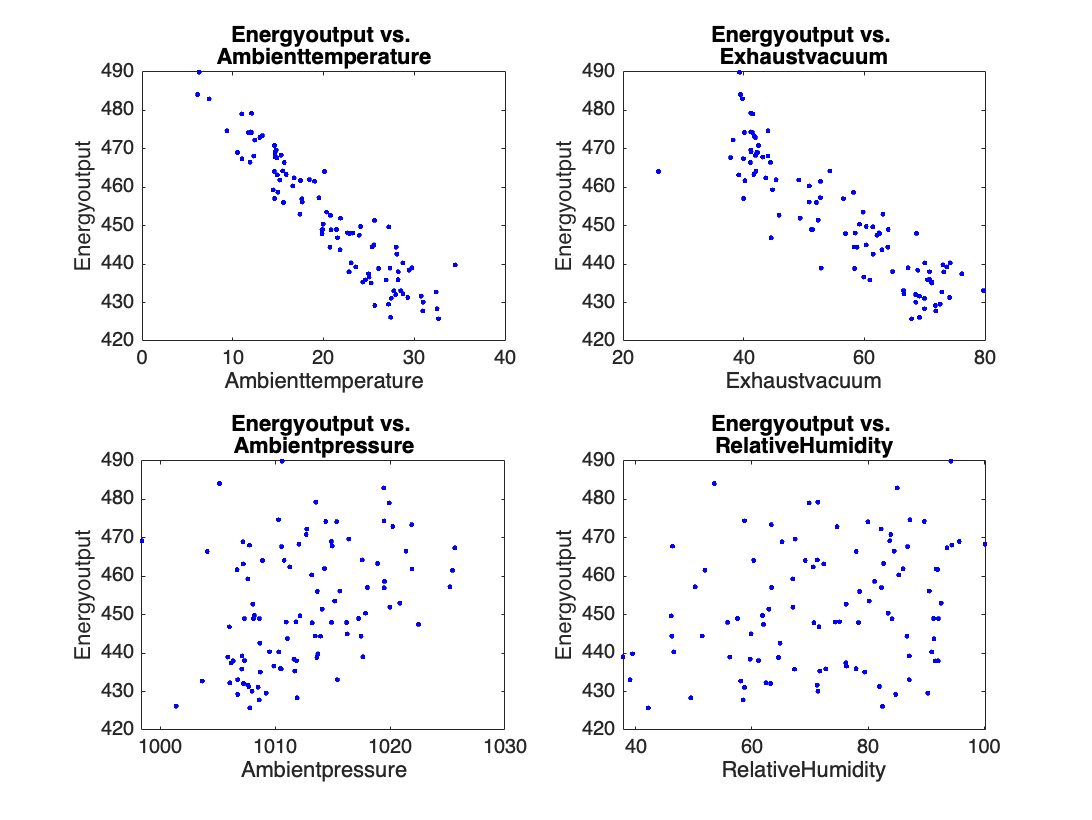

labels = ["Ambienttemperature" "Exhaustvacuum" "Ambientpressure" "RelativeHumidity" "Energyoutput"];
figure()
for(i=1:4)
    subplot(2,2,i)
    plot(pred_var(:,i),y,'b.')
    title(['Energyoutput vs. ' labels(i)])
    xlabel(labels(i))
    ylabel('Energyoutput')
end
hold off

As we had already noticed, we can remark that all the models seem to have an approximately linear relationship between the variables, except the one for Price and Length which has a either linear or quadratic relationship.

In general, what we have done until know does not give us a complete vision of the analysis so we are going to build a model considering all the four variables together.

We now try to determine the best linear model that fits the data, among those who satisfy:

$P_i = \beta_0 + \beta_1 \ell_i + \beta_2 w_i + \beta_3 s_i + \beta_4 h_i + \varepsilon_i$, $i = 1, \dots, m$,

where $m = 100$ and $\ell_i$, $w_i$, $s_i$, $h_i$, $P_i$, refer to the length, curb weight, engine size, horsepower, and price of the automobile, respectively.

To find the optimal coefficients of such a model we introduce:

$\mathbf y = \left[\matrix{P_1 \cr \vdots \cr P_m}\right]$, the vector of the response variable;

$X= \left[\matrix{1 & \ell_1 & w_1 & s_1 & h_1 \cr \vdots & \vdots &\vdots & \vdots & \vdots \cr 1 & \ell_m & w_m & s_m & h_m}\right]$, the design matrix;

$\mathbf \beta = \left[\matrix{\beta_0 \cr \beta_1 \cr \beta_2 \cr \beta_3 \cr \beta_4}\right]$, the vector of coefficients;

$\mathbf \varepsilon = \left[\matrix{\varepsilon_1 \cr \vdots \cr \varepsilon_m}\right]$, the vector of residuals.

From lectures, we know that we need to minimize the *residual sum of squares *$||\mathbf \varepsilon||^2 = ||\mathbf y - X \mathbf \beta||^2 =: f(\mathbf \beta)$,

that is, to find $\mathbf \beta$ that minimizes the distance between $\mathbf y$ and $X\mathbf \beta$ that can be done by solving the linear system $\mathbf y = X\mathbf \beta$ in the least-squares sense which, in turn, is equivalent to solving the normal equation

$X^TX \mathbf \beta = X^T \mathbf y$.

If $X$ has linearly independent columns (i.e., $X^TX$ is invertible), then *the* best linear model fitting the data has coefficients:

$\hat \mathbf \beta = (X^TX)^{-1}X^T\mathbf y$.

Luckily, in MATLAB it is much more easy to compute solutions to linear systems, both in the classical sense and in the least-squares sense, *via* the *backslash operator *`\`. Let's see how to do it:

m = length(y);
X = [ones(m,1) pred_var];
beta_hat = X\y

beta_hat =   409.0529
   -1.7881
   -0.3223
    0.1071
   -0.1457


## Task 2

We can notice that all values are pretty near to zero, except for the $\beta_0 $, which is negative. We expected this coefficient to be strictly positive as it is the interception with the t-axis (price). While all the other coefficients, as we know from simple linear regression, are the slopes of the relationship, which is obviously linear, between the response variable and the predictor variable, independently from the others.

Unluckily, having a multi linear regression case implies that we cannot represent graphically our results. 

## Task 3:

Since we are studying the automobiles, we can build other models that have as independent variables that have a stronger linear dependence with Price, which are all, except for Lenght and Horsepower.

- Curb-weight, engine size

## Task 4:

%extracting the predictors of interest
predictors1 = Powerplantdata(:, [2,3]);

% creating the design matrix
X_1 = [ones(m,1) predictors1];
beta_hat_1 = X_1\y

beta_hat_1 =    25.6293
   -1.0586
    0.4793


But, as we have already said, we cannot represent them graphically since the model takes into account multiple dimensions.

## Task 5:

As we have previously noticed, not all models give us a linear relationship, as in the case of Length-Price, it seems to be linear or quadratic. 

This is why we can try the data fitting, that is the process of constructing a curve that best fits our series of data points, possibly subject to constraints. 

In our case, looking at the graph, we can try a polynomial fitting for the model Length-Price. 

This polynomial pattern, geometrically, lets the data points near to the curve:

$y_i = \beta_0 + \beta_1 t_i + \beta_2 t_i^2 + \beta_3 t_i^3 + \epsilon_i, \, i=1,\dots,m$,

## Task 6:

% extracting the predictor variable
mx = Powerplantdata(:,[1 5])

mx =    26.9000  435.8700
   25.3700  444.4600
   24.6200  435.8800
   20.3400  453.5400
   19.8400  447.9200
   17.4000  453.0000
   22.8000  437.9800
   21.4300  449.0200
   25.0200  436.6400
   23.9400  447.5000


mx = sortrows(mx, 1)

mx =     6.1300  484.1200
    6.3000  489.9500
    7.3900  482.9900
    9.3600  474.6800
   10.5200  469.0300
   10.9800  479.0800
   11.0200  467.4100
   11.7100  474.2200
   11.9100  466.5200
   12.0000  474.4000


sorted_len = mx(:,1)

sorted_len =     6.1300
    6.3000
    7.3900
    9.3600
   10.5200
   10.9800
   11.0200
   11.7100
   11.9100
   12.0000


sorted_energyoutput = mx (: ,2)

sorted_energyoutput =   484.1200
  489.9500
  482.9900
  474.6800
  469.0300
  479.0800
  467.4100
  474.2200
  466.5200
  474.4000



m = length(sorted_len);
X_ll = [ones(m,1) sorted_len sorted_len.^2];
beta_hat_ll = X_ll\sorted_energyoutput

beta_hat_ll =   510.4360
   -3.6514
    0.0360


## Task 7:

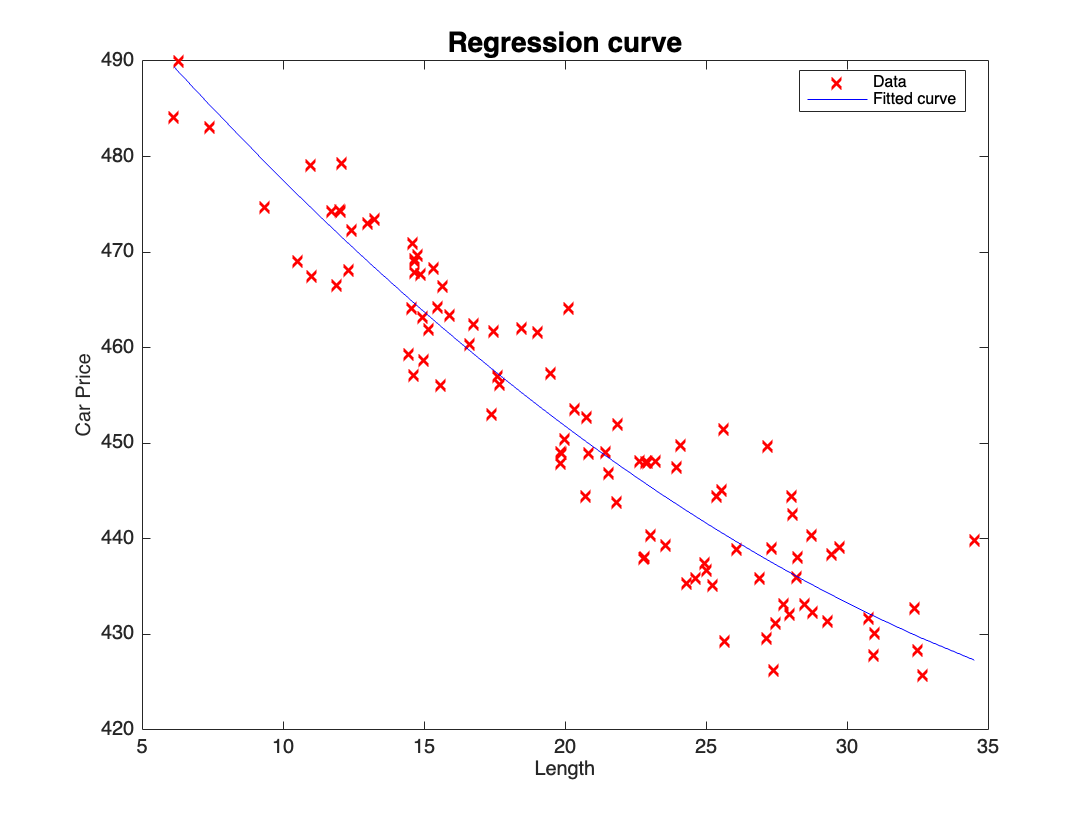

fitted_ll = X_ll*beta_hat_ll;
figure()
plot(sorted_len,sorted_energyoutput,'rx','MarkerSize',6,'LineWidth',2)
title('Regression curve','FontSize',14)
xlabel('Length','FontSize',10)
ylabel('Car Price','FontSize',10)
hold on
plot(sorted_len,fitted_ll,'b-')
legend('Data','Fitted curve','FontSize',8,'Location','best')
hold off

## Task 8:

For what regards the polynomial model, we can notice that the interception with the y-axis is strictly positive, so we can probably trust these results. In particular, about the coefficients we say that:

- $\beta_0$: gives the estimated initial price of the automobiles;

- $\beta_1$: gives the rate of the change of price with respect to length (for instance, if the length of the car increases by 1, the price of the car increases by $\beta_1$)

- $\beta_2$: the longer the car, the greater the increment of price;

## Task 9:

**RMSE for the model considering all the predictors:**

fitted_all = X*beta_hat; % Fitted values
lse_all = norm(y - fitted_all) % The least-squares error

lse_all = 41.8180

disp(sprintf('The least-squares error is: %.3f', lse_all))

The least-squares error is: 41.818


rss_all = lse_all^2 % The residual sum of squares

rss_all = 1.7487e+03

disp(sprintf('The residual sum of squares is: %.3f', rss_all))

The residual sum of squares is: 1748.743


mse_all = rss_all/m % The mean square error

mse_all = 17.4874

disp(sprintf('The mean square error is: %.3f', mse_all))

The mean square error is: 17.487


rmse_all = sqrt(mse_all) % The root mean square error

rmse_all = 4.1818

disp(sprintf('The root mean square error is: %.3f', rmse_all))

The root mean square error is: 4.182


**RMSE for the model (Curb-weight, engine size)-price:**

fitted_1 = X_1*beta_hat_1; % Fitted values
lse_1 = norm(y - fitted_1) % The least-squares error

lse_1 = 66.8899

disp(sprintf('The least-squares error is: %.3f', lse_1))

The least-squares error is: 66.890


rss_1 = lse_1^2 % The residual sum of squares

rss_1 = 4.4743e+03

disp(sprintf('The residual sum of squares is: %.3f', rss_1))

The residual sum of squares is: 4474.256


mse_1 = rss_1/m % The mean square error

mse_1 = 44.7426

disp(sprintf('The mean square error is: %.3f', mse_1))

The mean square error is: 44.743


rmse_1 = sqrt(mse_1) % The root mean square error

rmse_1 = 6.6890

disp(sprintf('The root mean square error is: %.3f', rmse_1))

The root mean square error is: 6.689


**RMSE for the polynomia model :**

fitted_p = X_ll*beta_hat_ll; % Fitted values
lse_p = norm(y - fitted_p) % The least-squares error

lse_p = 235.9858

disp(sprintf('The least-squares error is: %.3f', lse_p))

The least-squares error is: 235.986


rss_p = lse_p^2 % The residual sum of squares

rss_p = 5.5689e+04

disp(sprintf('The residual sum of squares is: %.3f', rss_p))

The residual sum of squares is: 55689.317


mse_p = rss_p/m % The mean square error

mse_p = 556.8932

disp(sprintf('The mean square error is: %.3f', mse_p))

The mean square error is: 556.893


rmse_p = sqrt(mse_p) % The root mean square error

rmse_p = 23.5986

disp(sprintf('The root mean square error is: %.3f', rmse_p))

The root mean square error is: 23.599


# **MATLAB PROJECT: THIRD PART**

## **Task 1:**

We insert all our independent variables inside the variable 'all'. Then, we compute the eigenvalues and eigenverctors of our squared matrix. An **eigenvector** is a nonzero vector that changes at most by a scalar factor when that linear transformation is applied to it. The corresponding **eigenvalue**, often denoted by $\lambda$, is the factor by which the eigenvector is scaled.

all = Powerplantdata(:,[1,2,3,4])

all = 1.0e+03 *

    0.0269    0.0609    1.0071    0.0673
    0.0254    0.0583    1.0135    0.0514
    0.0246    0.0705    1.0106    0.0727
    0.0203    0.0598    1.0152    0.0802
    0.0198    0.0569    1.0132    0.0783
    0.0174    0.0631    1.0208    0.0926
    0.0228    0.0732    1.0119    0.0916
    0.0214    0.0639    1.0173    0.0575
    0.0250    0.0599    1.0099    0.0763
    0.0239    0.0621    1.0225    0.0620


s = corrcoef(all)

s =     1.0000    0.8470   -0.3404   -0.4519
    0.8470    1.0000   -0.2412   -0.2176
   -0.3404   -0.2412    1.0000   -0.0743
   -0.4519   -0.2176   -0.0743    1.0000


[m,n] = size(all)

m = 100

n = 4

[P,D]= eig(s,'vector') %option vector puts eigenvalues into a vector, rather then a diagonal matrix

P =     0.7450    0.1146   -0.0279   -0.6565
   -0.6070    0.5150    0.0656   -0.6017
    0.1390    0.6000   -0.7311    0.2936
    0.2392    0.6014    0.6785    0.3475


D =     0.1013
    0.6534
    1.0777
    2.1676


## **Task 2:**

Here, we determine the proportion of total sample variance.

We first need to sort eigenvalues in descending order to associate the first component to the highest eigenvalue and so on.

eigval_cor = sort(D,'descend')

eigval_cor =     2.1676
    1.0777
    0.6534
    0.1013


totalvar_cor = sum(eigval_cor)

totalvar_cor = 4.0000

prop_cor = eigval_cor./totalvar_cor;       

And here we plot the scree plot. It is a plot of the eigenvalues of factors or principal components in an analysis. The scree plot is used to determine the number of principal components to keep in a principal component analysis (PCA).

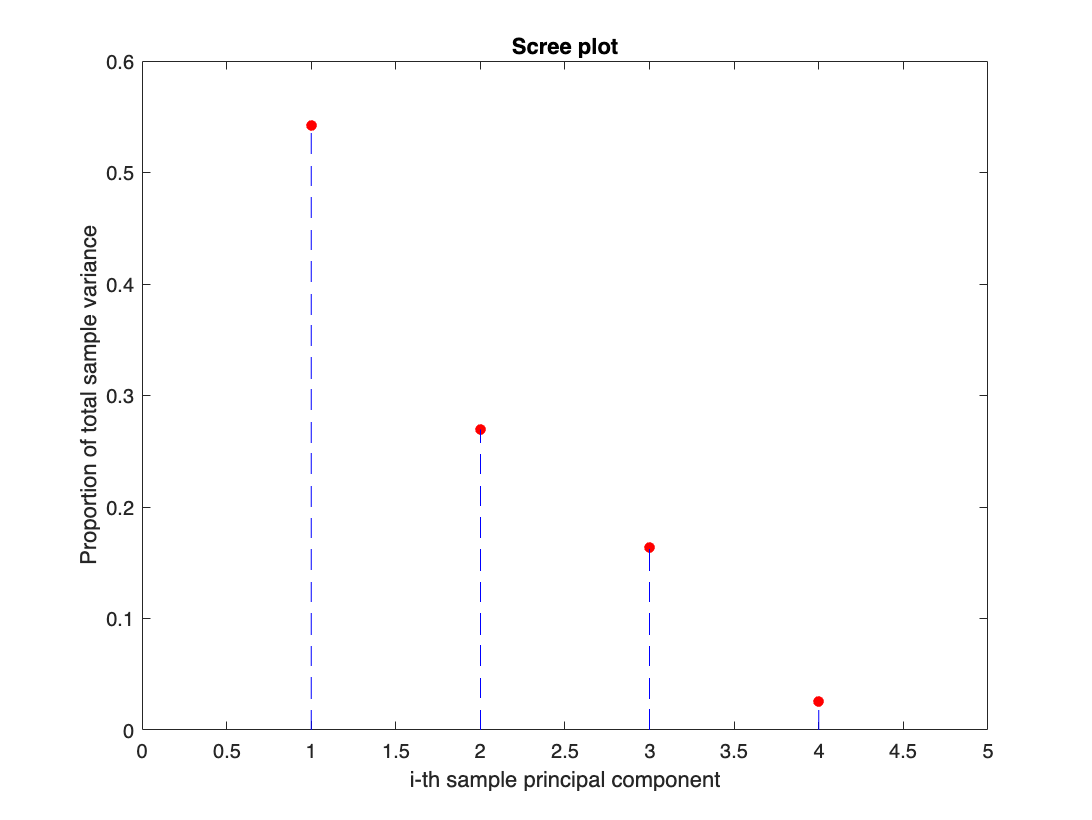

figure();
plot([1:n],prop_cor,'r.','MarkerSize',16)
xlim([0 n+1]);
hold on
for k = 1:n
    N = 100;
    x = k*ones(N);
    y = linspace(0,prop_cor(k),N);
    plot(x,y,'b--')
end
xlabel('i-th sample principal component')
ylabel('Proportion of total sample variance')
title('Scree plot')
hold off

Let $\lambda_1 \ge \lambda_2 \ge \cdots \ge \lambda_n >0$ be the eigenvalues of the sample variance matrix. From lecture we know that the total sample variance equals $\sum_{j=1}^n \lambda_j$ and that the proportion of total sample variance is:

                                             
$$\frac{\lambda_j }{\lambda_1 +\cdots +\lambda_n },~~j=1,\ldots,n\ldotp$$


In our scree plot:

- On the x-axis we put a label for each eigenvalue;

- On the y-axis we visualize the proportion of total sample variance explained by the -th principal component.

## Task 3:

In this task, we want to get the cumulative proportion plot of the total sample variance. Proportion of variance is a normalized version of the eigenvalues. This curve displays the specific proportion of the total variance explained by each principal component.

cumul_cor = cumsum(eigval_cor);         
cumulprop_cor = cumul_cor./totalvar_cor;

The line represents the cumulative proportion of sample variance explained by all the principal components. Anyway, we have noticed that taking only the first principal component we reach almost 90% of variability.

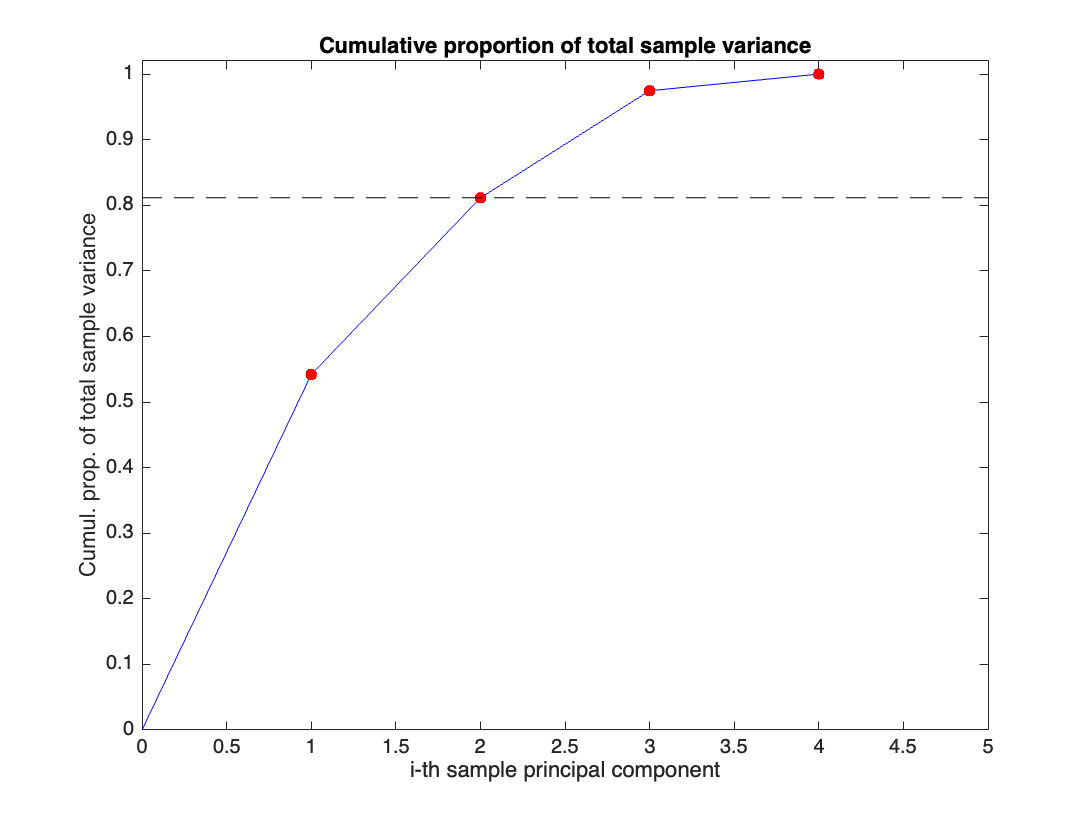

plot([0:n],[0; cumulprop_cor], 'b-')
hold on
plot([1:n],cumulprop_cor,'r.','MarkerSize',16)
xlim([0 n+1])
ylim([0 1.02])
plot(linspace(0,n+1,100),cumulprop_cor(2)*ones(100),'k--') 
xlabel('i-th sample principal component')
ylabel('Cumul. prop. of total sample variance')
title('Cumulative proportion of total sample variance')

We obtain:

disp(sprintf('The first sample principal component explains %.3f%% of variability', 100*cumulprop_cor(1)))

The first sample principal component explains 54.191% of variability


for(i=2:n)
    disp(sprintf('The first %d sample principal components explain %.3f%% of variability', i, 100*cumulprop_cor(i)))
end

The first 2 sample principal components explain 81.132% of variability
The first 3 sample principal components explain 97.467% of variability
The first 4 sample principal components explain 100.000% of variability


## Task 4:

The loading of each sample principle component is the coefficient of the linear combination of a single variable in our dataset. 

The loadings represent the coordinates of the corresponding eigenvector of the sample variance matrix and they can be interpreted as the weights that each variable in the dataset has in the sample principal component.

To get the loadings in the correct form, we need to reverse the order of the columns of the matrix P.

for i = 1:n
    loadings_corr(:,i) = P(:,end-i+1);
end

The loadings of the first principal component are:

loadings_corr(:,1)

ans =    -0.6565
   -0.6017
    0.2936
    0.3475


The first principal component is: ${\mathbf{y}}_1 =0\ldotp 48{\mathbf{x}}_1 +0\ldotp 52{\mathbf{x}}_2 +0\ldotp 50{\mathbf{x}}_3 +0\ldotp 49{\mathbf{x}}_4$

The coefficients of the loading are a kind of weighted average of the variables in the dataset. It can be interpreted as the structural* components* of the car.

loadings_corr(:,2)

ans =    -0.0279
    0.0656
   -0.7311
    0.6785


The second principal components captures the* elements component *and it is: ${\mathbf{y}}_2 =0\ldotp 74{\mathbf{x}}_1 +0\ldotp 11{\mathbf{x}}_2 -0\ldotp 22{\mathbf{x}}_3 -0\ldotp 63{\mathbf{x}}_4$

In this case, we can see that two out of the four coefficients are negative. We can notice a contrast between a weighted average of the variables corresponding to the physical characteristics of the car and a weighted average of the variables corresponding to the engine of a car.

## Task 5

Observations in the principal components are called scores.

By using the build-in function *diag, *we extract the diagonal elements of the sample matrix, then we take the square root. Doing this we are able to obtain sample standard deviations.

avg = mean(all)

avg = 1.0e+03 *

    0.0207    0.0557    1.0124    0.0727


dev_std = sqrt(diag(s));
for i = 1:m
    data_std(i,:) = (all(i,:) - avg)./dev_std';
end
scores = data_std*loadings_corr;

## Task 6:

We plot the scores in the plane generated by the first two eigenvectors.

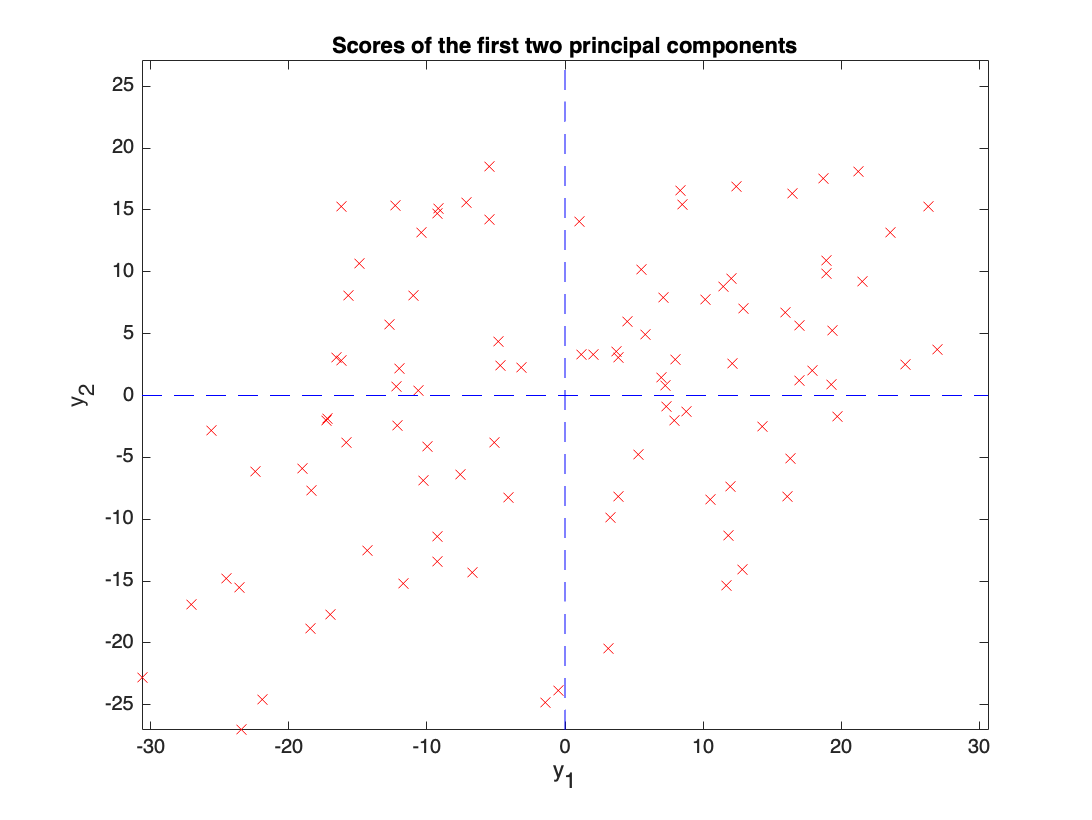

figure()
plot(scores(:,1), scores(:,2),'rx')
eps = 0.01;
xmax = max(abs(scores(:,1))) + eps; % Values to set the ranges of the axes. Add
ymax = max(abs(scores(:,2))) + eps; % eps to have some margin.
xlim([-xmax xmax])
ylim([-ymax ymax])
hold on
N = 100;
x = linspace(-xmax, xmax, N); 
y = linspace(-ymax, ymax, N);
plot(x,zeros(N),'b--')
plot(zeros(N),y,'b--')
xlabel('y_1')
ylabel('y_2')
title('Scores of the first two principal components')